# Non-invasive Glucose Monitor Simulation with Physiological Variations

This simulation models a NIR-based glucose monitoring system with realistic physiological variations including different skin types, tissue scattering, and blood perfusion levels. 

### Simulation Parameters

% Time parameters
num_samples = 1000;          % Number of time points
sampling_rate = 100;         % Hz
t = (0:num_samples-1)/sampling_rate;  % Time vector

% Glucose levels to simulate (mg/dL)
glucose_levels = [80, 120, 180];  
num_levels = length(glucose_levels);

#### Physiological Parameters

% Skin types (Fitzpatrick scale I-VI)
skin_types = struct('melanin_conc', {0.015, 0.025, 0.035, 0.045, 0.055, 0.065}, ...
                   'description', {'Type I', 'Type II', 'Type III', 'Type IV', 'Type V', 'Type VI'});

% Tissue parameters
tissue_params = struct(...
    'water_content', 0.7, ...           % Typical water content in tissue
    'scattering_coeff', 10, ...         % Base scattering coefficient
    'anisotropy', 0.9, ...              % Anisotropy factor
    'layer_thickness', [0.1, 0.2, 2]);  % Thickness of epidermis, dermis, subcutaneous tissue (mm)


#### NIR Light Parameters

wavelength_nm = 1550;  % NIR wavelength in nanometers

% Absorption coefficients vary with glucose concentration
base_absorption_coeff = 0.3;
glucose_sensitivity = 0.01;  % Change in absorption per 100 mg/dL


#### Initializing Arrays

num_skin_types = length(skin_types);
nir_signals = zeros(num_levels, num_samples, num_skin_types);
noisy_signals = zeros(num_levels, num_samples, num_skin_types);
filtered_signals = zeros(num_levels, num_samples, num_skin_types);


#### Generate Physiological Variations

% Blood perfusion variation (cardiac cycle)
heart_rate = 1.2; % Hz
perfusion_variation = 0.1 * sin(2*pi*heart_rate*t);

% Respiratory effect
resp_rate = 0.2; % Hz
resp_variation = 0.05 * sin(2*pi*resp_rate*t);

% Temperature fluctuation
temp_variation = 0.02 * sin(2*pi*0.1*t);

#### Generate Signals for Each Skin Type and Glucose Level

for skin_idx = 1:num_skin_types
    % Calculate skin-specific attenuation
    melanin_attenuation = exp(-skin_types(skin_idx).melanin_conc * 100);
    
    for glucose_idx = 1:num_levels
        % Calculate glucose-dependent absorption
        absorption_coeff = base_absorption_coeff + ...
            glucose_sensitivity * (glucose_levels(glucose_idx)/100);
        
        % Base NIR signal with Beer-Lambert law
        base_signal = exp(-absorption_coeff * glucose_levels(glucose_idx)/100);
        
        % Add tissue scattering effect
        scattering_effect = exp(-tissue_params.scattering_coeff * ...
            (1 - tissue_params.anisotropy));
        
        % Combine all physiological effects
        physiological_variation = (1 + perfusion_variation + resp_variation + temp_variation);
        
        % Generate final clean signal
        nir_signals(glucose_idx,:,skin_idx) = base_signal * melanin_attenuation * ...
            scattering_effect * physiological_variation;
        
        % Add noise and artifacts
        noise = randn(size(t))/20;  % Gaussian noise
        motion_artifact = 0.15 * sin(2*pi*1.2*t);  % Motion artifact
        tissue_noise = 0.05 * randn(size(t));  % Tissue heterogeneity noise
        
        % Combine signal with noise
        noisy_signals(glucose_idx,:,skin_idx) = nir_signals(glucose_idx,:,skin_idx) + ...
            noise + motion_artifact + tissue_noise;
    end
end


#### Signal Processing and Filtering

% Design bandpass filter
nyquist = sampling_rate/2;
low_cutoff = 0.05/nyquist;
high_cutoff = 15/nyquist;
[b, a] = butter(4, [low_cutoff high_cutoff], 'bandpass');

% Apply filtering
for skin_idx = 1:num_skin_types
    for glucose_idx = 1:num_levels
        filtered_signals(glucose_idx,:,skin_idx) = filtfilt(b, a, ...
            noisy_signals(glucose_idx,:,skin_idx));
    end
end


#### Visualization

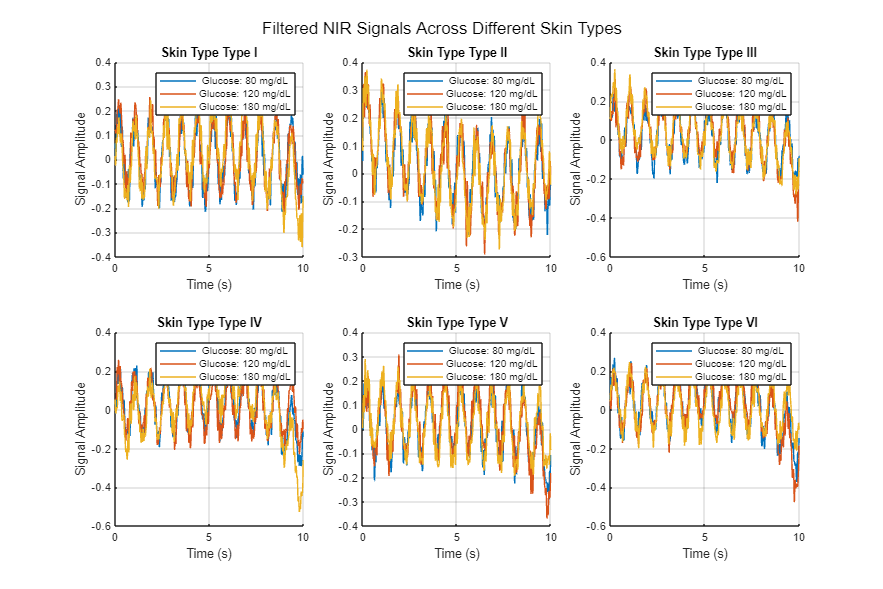

% Plot signals for each skin type
figure('Position', [100 100 1200 800])
for skin_idx = 1:num_skin_types
    subplot(2,3,skin_idx)
    hold on
    for glucose_idx = 1:num_levels
        plot(t, filtered_signals(glucose_idx,:,skin_idx))
    end
    title(['Skin Type ', skin_types(skin_idx).description])
    xlabel('Time (s)')
    ylabel('Signal Amplitude')
    legend(cellstr(num2str(glucose_levels', 'Glucose: %d mg/dL')))
    grid on
    hold off
end
sgtitle('Filtered NIR Signals Across Different Skin Types')

#### Glucose Estimation

estimated_glucose = zeros(num_levels, num_skin_types);
for skin_idx = 1:num_skin_types
    for glucose_idx = 1:num_levels
        mean_signal = mean(filtered_signals(glucose_idx,:,skin_idx));
        estimated_glucose(glucose_idx,skin_idx) = ...
            -100 * log(mean_signal) / (base_absorption_coeff + glucose_sensitivity);
    end
end


#### Error Analysis

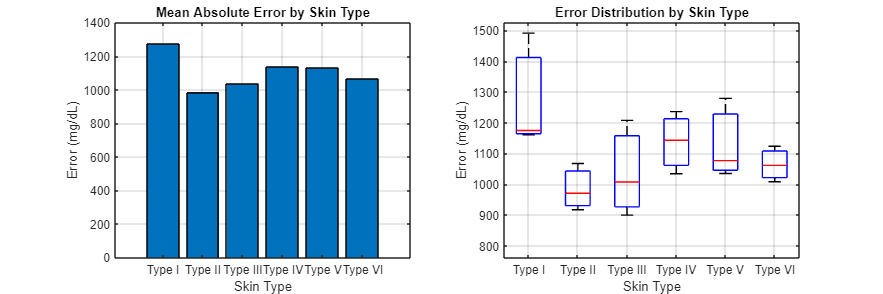

% Calculate errors for each skin type
errors = zeros(num_levels, num_skin_types);
mean_errors = zeros(1, num_skin_types);
for skin_idx = 1:num_skin_types
    errors(:,skin_idx) = abs(glucose_levels' - estimated_glucose(:,skin_idx));
    mean_errors(skin_idx) = mean(errors(:,skin_idx));
end

% Plot error analysis
figure('Position', [100 100 1200 400])
subplot(1,2,1)
bar(mean_errors)
set(gca, 'XTickLabel', {skin_types.description})
title('Mean Absolute Error by Skin Type')
xlabel('Skin Type')
ylabel('Error (mg/dL)')
grid on

subplot(1,2,2)
boxplot(errors)
set(gca, 'XTickLabel', {skin_types.description})
title('Error Distribution by Skin Type')
xlabel('Skin Type')
ylabel('Error (mg/dL)')
grid on

#### Results Table

% Create results table
results_table = table;
results_table.SkinType = {skin_types.description}';
results_table.MeanError = mean_errors';
results_table.StdError = std(errors)';
results_table.MaxError = max(errors)';
results_table.MinError = min(errors)';

% Display results
disp('Performance Analysis Across Skin Types:')

Performance Analysis Across Skin Types:


disp(results_table)

      SkinType      MeanError    StdError    MaxError    MinError
    ____________    _________    ________    ________    ________

    {'Type I'  }     1275.2       186.99        1491      1160.2 
    {'Type II' }     984.84       76.198      1067.2      916.76 
    {'Type III'}       1038       156.36      1207.5       899.5 
    {'Type IV' }     1137.6       101.16        1236      1033.9 
    {'Type V'  }     1130.1       130.62        1279      1034.8 
    {'Type VI' }     1064.1       57.813      1123.3      1007.8 



#### Save Results

save('glucose_monitor_results.mat', 'estimated_glucose', 'errors', 'results_table')
writetable(results_table, 'glucose_monitor_results.csv')